## Measure the elongation rate of RNAP using MS2 loops at different locations along a gene.

We have been given a set of images corresponding to RNA polymerase molecules on both the 5' and 3' ends of DNA. Each dot is a GFP tag attached to the RNApol transcribing the gene.

First, let's look at an image. Load it using `imread` and show it using `imshow`.

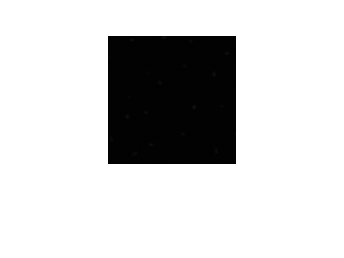

Image=imread('5loops070.tif');
imshow(Image)

Why do we get a black image? Let's look a the "data type"

whos Image

  Name         Size             Bytes  Class     Attributes

  Image      128x128            32768  uint16              



Note that an uint16 can encode for 65k levels of gray. Howerver, Matlab can only display 256 levels. We need to map the 65k onto 256.

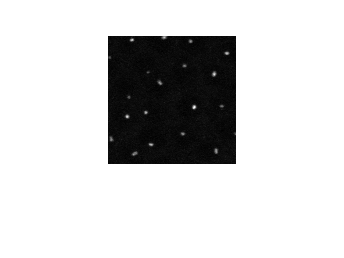

imshow(Image, [])

The [] tells Matlab to grab the lowest pixel value and assign it to zero and the assign the highest pixel value to 255 (making a total of 256 values).

Strategy: count number of spots vs time. To make this possible, first I need to be able to separate spots from background by drawing a threshold.

To find the threshold, we use `imtool` and use the "Inspect Pixel Values" command.

%imtool(Image, [])

We decided on a threshold value of 1000. Note that I'm going to comment `imtool` out using % so it doesn't create a new window every time I run the script.

Now, draw the threshold.

%Recall
a=[1,2,3,4,5];
a>2

ans = 1×5 logical array
   0   0   1   1   1


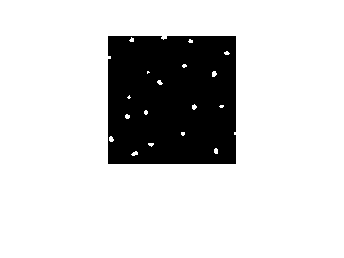

Threshold=1000;
ImThresh=Image>Threshold;
imshow(ImThresh)

We want to label each spot we found individually in order to count them. This can be done with the function `bwlabel`. Admittedly, this function is kind of a black box, but the end result is that all the pixels in each spot share their own color value, but no two different spots share a value.

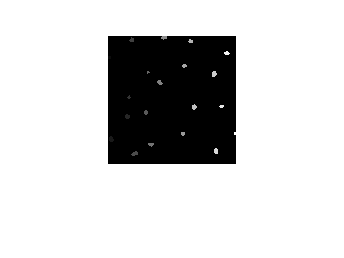

ImLabel=bwlabel(ImThresh);
imshow(ImLabel, [])

To count the number of spots, I just need to find the maximum pixel value within this image using the function `max`.

a=[1,2,3;4,5,6;7,8,9]

a =      1     2     3
     4     5     6
     7     8     9


max(a)

ans =      7     8     9


max(max(a))

ans = 9

Nspots=max(max(ImLabel))

Nspots = 20

This process works to count the number of spots for one image. If we want to compare how the number of spots changes over time between the 5' and 3' ends, we'll need to set up two for-loops - one for each end of the DNA.

- Get file list

- for-loop over files (i=1:num_frames)

- Make a plot comparing 5' and 3' data

How do you get a list of files? We learned that we can do

D=dir('*.tif');

to get a list of all .tif files. To get a list of just the 3Loops files (or the 5Loops files), do

Three=dir('FlyElongationData/3Loops*.tif');
Five=dir('FlyElongationData/5Loops*.tif');

Now let's set up some empty lists for our final counts of # spots per frame and run them through the for-loop. We'll also define a time vector. I know that the frame rate is 1/(10 s).

time = (1:length(Three))*10; %in s
spots3 = zeros(148);
spots5 = zeros(148);

for i=1:148 %148 frames per movie
    time(i)=i;
    
    Image3=imread(Three(i).name);
    Image5=imread(Five(i).name);
    
    Threshold=1000;
    ImThresh3=Image3>Threshold;
    ImThresh5=Image5>Threshold;
    
    ImLabel3=bwlabel(ImThresh3);
    ImLabel5=bwlabel(ImThresh5);
    
    spots3(i)=max(max(ImLabel3));
    spots5(i)=max(max(ImLabel5));
end

Finally, we'll set up a plot to compare both elongation rates.

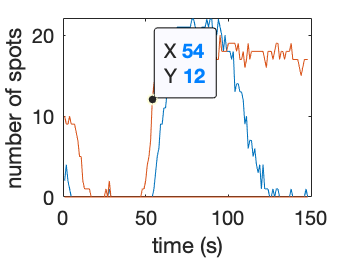

plot(time, spots3)
hold on
plot(time, spots5)
xlabel('time (s)')
ylabel('number of spots')
hold off